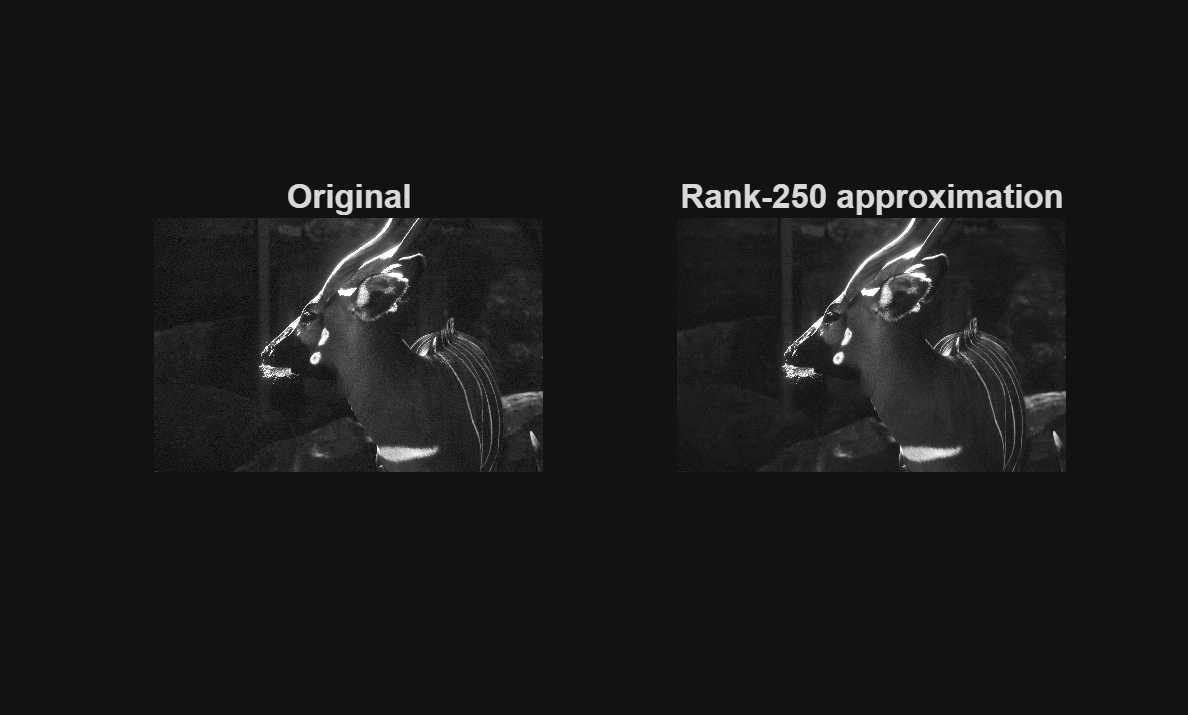


clear
asset_path = "../docs/assets/";
% Discrete Cosine Transform compression
% See https://www.mathworks.com/help/images/discrete-cosine-transform.html
A = imread('theory/deer.pgm');
if size(A, 3) == 3
    A = rgb2gray(A);
end
A = im2double(A);

% Compute SVD
[U, S, V] = svd(A);

% Keep top k singular values
k = 250;
A_k = U(:,1:k) * S(1:k,1:k) * V(:,1:k)';

% Display
figure;
subplot(1,2,1); imshow(A); title('Original');
subplot(1,2,2); imshow(A_k); title(['Rank-' num2str(k) ' approximation']);


compressed_size = k * (size(A, 1) + size(A, 2) + 1)

compressed_size = 1671250

size_fraction = compressed_size / (size(A, 1)*size(A, 2))

size_fraction = 0.1565